warning off;
clear all;
clc


Nbps=1; 
M=2^Nbps;           % Modulation order=2/4/6 for QPSK/16QAM/64QAM
EbN0=0:5:25;        % EbN0, SNR
N_iter=8000;         % no of packets   % Number of iterations for each EbN0
Nframe=1;           % no. of sybmols in on % Number of symbols per frame

norms=[1 sqrt(2) 0 sqrt(10) 0 sqrt(42)];

## Bob,Eve

PowerdB=[0 -8 -17 -21 -25]; % Channel tap power profile 'dB'
Delay=[0 3 5 6 8];          % Channel delay 'sample'
Power=10.^(PowerdB/10);     % Channel tap power profile 'linear scale'
Power=Power/(sum(Power));
Ntap=length(PowerdB);       % Chanel tap number
Lch=Delay(end)+1;           %Channel length

Nfft=64;           % FFT size
Ng=16;             % Ng=0: Guard interval length
Nsym=Nfft+Ng;      % Symbol duration
Nused=Nfft ;

NgType=1; % NgType=1/2 for cyclic prefix/zero padding
if NgType==1, nt='CP';  elseif NgType==2, nt='ZP';   end

for k=1:length(EbN0)
     BERu1=0;
     BERu2=0;
     BERu1E=0;
     BERu2E=0;
     
     BERIu1=0;
     BERIu2=0;
     
     TERu1=0;
     TERu2=0;
     TERu1E=0;
     TERu2E=0;
     
     bittot=0;
     
     for m=1:N_iter

## Round 1 antenna 1

          %h_ab  a=usr b=antena
      %user1
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);
       h11=zeros(1,Lch); 
       h11(Delay+1)=channel; % cir: channel impulse response
       h11r1=h11;
       H11r1=fft([h11r1 zeros(1,Nfft-Lch)]); % Channel frequency response
      %user2
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);
       h21=zeros(1,Lch); 
       h21(Delay+1)=channel; % cir: channel impulse response
       h21r1=h21;
       H21r1=fft([h21r1 zeros(1,Nfft-Lch)]); % Channel frequency response
      
       %Eve
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);
       hE1=zeros(1,Lch); 
       hE1(Delay+1)=channel; % cir: channel impulse response
       hEr1=hE1;
       HEr1=fft([hEr1 zeros(1,Nfft-Lch)]); % Channel frequency response

## Round 2 antenna 2

       %h_ab  a=usr b=antena
   
      %user1  
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);	
       h12=zeros(1,Lch); 
       h12(Delay+1)=channel; % cir: channel impulse response
       h12r2=h12;
       H12r2=fft([h12r2 zeros(1,Nfft-Lch)]); % Channel frequency response
      
      % user2
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);	
       h22=zeros(1,Lch); 
       h22(Delay+1)=channel; % cir: channel impulse response
       h22r2=h22;
       H22r2=fft([h22r2 zeros(1,Nfft-Lch)]); % Channel frequency response
     
       %Eve
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);	
       hE2=zeros(1,Lch); 
       hE2(Delay+1)=channel; % cir: channel impulse response
       hEr2=hE2;
       HEr2=fft([hEr2 zeros(1,Nfft-Lch)]); % Channel frequency response

## Generate Signal for each user/tx, modulate, and add CP

      % User1 Tx______________________________________________________________
      X= randi([0,M-1], Nused*Nframe,1)'; % bit: integer vector (1)
      Xmod= qammod(X,M,'gray')/norms(Nbps); 	
      
      % User2 Tx______________________________________________________________
      X2= randi([0,M-1], Nused*Nframe,1)'; % bit: integer vector
      Xmod2= qammod(X2,M,'gray')/norms(Nbps);
      
      %%Modulted signal for user1 and user2      
      U1=Xmod;
      U2=Xmod2;

## Auxiliary signals

      %h_ab  a=usr b=antena

        A = abs(diag(H11r1)).^(2);
        B = abs(diag(H12r2)).^(2);
        C = abs(diag(H21r1)).^(2);
        D = abs(diag(H22r2)).^(2);
        
        
        S = -((A+B)*diag(U2));
        T = -((C+D)*diag(U1));
        
        r2 = ((S*C)-(A*T))/((B*C)-(A*D));
        r1 = (T-(D*r2))/C;

## Super position

        %%Antenna 1 unity power
       Tx1=sqrt(1)*U1+sqrt(1)*U2+sqrt(1)*diag(r1)';
        %%Antenna 2    
       Tx2=sqrt(1)*U1+sqrt(1)*U2+sqrt(1)*diag(r2)';

## FOR PAPR

     x1np= ifft(U1);
     x_GI1np= guard_interval(Ng,Nfft,NgType,x1np);       
     x2np= ifft(U2);
     x_GI2np= guard_interval(Ng,Nfft,NgType,x2np);

       %Tx1
         x1= ifft(Tx1)/norm(ifft(Tx1),2);  %% This is how i am normalizign it :step1
         norm(ifft(Tx1),2);
         
        % pause()
         x_GI1= guard_interval(Ng,Nfft,NgType,x1);       
         y11= conv(x_GI1,h11r1); %u1 r1
         y21=(conv(x_GI1,h21r1)); %u2 r1
         yE1= conv(x_GI1,hEr1); %u2 r1
         
         %EbN0=20;
         snr = EbN0(k)+10*log10(Nbps*(Nused/Nfft)); % SNR vs. Eb/N0
        %snr=snr/2;
         EEs=sum(x1).^2/length(x1);    
         %EEs=1;
         noise_mag  = sqrt(0.5*EEs*((10.^(-snr/10))));
         
         n11 = noise_mag*(randn(size(y11))+1i*randn(size(y11)));
         n12 = noise_mag*(randn(size(y21))+1i*randn(size(y21)));
         
         y_G11r1 = norm(ifft(Tx1),2)*y11+ n11; %% This is how i am normalizign : step2
         y_G21r1 = norm(ifft(Tx1),2)*y21+ n12;
         y_G21E1 = norm(ifft(Tx1),2)*yE1+ noise_mag*(randn(size(yE1))+1i*randn(size(yE1)));
 
         
         Y11= fft(remove_GI(Ng,Nsym,NgType,y_G11r1));
         Y21= fft(remove_GI(Ng,Nsym,NgType,y_G21r1));
         YE1= fft(remove_GI(Ng,Nsym,NgType,y_G21E1));

       %Tx2 
         x2= ifft(Tx2)/norm(ifft(Tx2),2);
         x_GI2= guard_interval(Ng,Nfft,NgType,x2);       
         y12=conv(x_GI2,h12r2); %u1 r2
         y22= conv(x_GI2,h22r2); %u2 r2
         yE2= conv(x_GI2,hEr2); %u2 r1 
         
         % %%%%%%% FOR PAPR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
         
         if k==1
         PAPRtx1(1,m)=max((abs(x_GI1)).^2)/mean((abs(x_GI1)).^2);
         PAPRtx2(1,m)=max((abs(x_GI2)).^2)/mean((abs(x_GI2)).^2);
         PAPRtx3(1,m)=max((abs(x_GI1np)).^2)/mean((abs(x_GI1np)).^2);
         PAPRtx4(1,m)=max((abs(x_GI2np)).^2)/mean((abs(x_GI2np)).^2);
         %pause();
         end
         
         % %%%%%%% FOR PAPR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
         %EbN0=10;
  
        EEs=sum(x2).^2/length(x2);    
        noise_mag  = sqrt(0.5*EEs*((10.^(-snr/10)))); 
        n21 = noise_mag*(randn(size(y12))+1i*randn(size(y12)));
        n22 = noise_mag*(randn(size(y22))+1i*randn(size(y22)));
        y_G12r2 = norm(ifft(Tx2),2)* y12+ n21;
        y_G22r2 = norm(ifft(Tx2),2)* y22+ n22;
        y_G21E2 = norm(ifft(Tx2),2)*yE2+ noise_mag*(randn(size(yE2))+1i*randn(size(yE2)));
 
        Y12= fft(remove_GI(Ng,Nsym,NgType,y_G12r2));
        Y22= fft(remove_GI(Ng,Nsym,NgType,y_G22r2));
        YE2= fft(remove_GI(Ng,Nsym,NgType,y_G21E2));

         YU1= (H11r1)'.*transpose(Y11)+(H12r2)'.*transpose(Y12);
         YU2= (H21r1)'.*transpose(Y21)+(H22r2)'.*transpose(Y22);
         YUe= YE1+YE2;
                
         %%Demodulate
         UU1i=qamdemod(YU1*norms(Nbps),M,'gray');
         UU2i=qamdemod(YU2*norms(Nbps),M,'gray');
         UUee=qamdemod(YUe*norms(Nbps),M,'gray');

## BER

          BERu1= BERu1+sum(sum(de2bi(UU1i,Nbps)~=de2bi(X,Nbps)));
          BERu1p(k,m)=sum(sum(de2bi(UU1i,Nbps)~=de2bi(X,Nbps))); %for PER
          BERu2= BERu2+sum(sum(de2bi(UU2i,Nbps)~=de2bi(X2,Nbps)));
          BERu2p(k,m)=sum(sum(de2bi(UU2i,Nbps)~=de2bi(X2,Nbps))); %for PER
          
          %%Internal Eve
          BERIu1= BERIu1+sum(sum(de2bi(UU1i,Nbps)~=de2bi(X2,Nbps))); %data send to user-2 seen by user-1
          BERIu2= BERIu2+sum(sum(de2bi(UU2i,Nbps)~=de2bi(X,Nbps)));% user-2 is the eavesdrop         
          
          %%External Eve
          BERu1E=BERu1E+sum(sum(de2bi(UUee,Nbps)~=de2bi(X,Nbps)));
          BERu1Ep(k,m)=sum(sum(de2bi(UUee,Nbps)~=de2bi(X,Nbps)));
          BERu2E=BERu2E+sum(sum(de2bi(UUee,Nbps)~=de2bi(X2,Nbps)));
          BERu2Ep(k,m)=sum(sum(de2bi(UUee,Nbps)~=de2bi(X2,Nbps)));

## Throughput

          TERu1=TERu1+(Nfft*Nbps)-sum(sum(de2bi(UU1i,Nbps)~=de2bi(X,Nbps))); 
          TERu2=TERu2+(Nfft*Nbps)-sum(sum(de2bi(UU2i,Nbps)~=de2bi(X2,Nbps)));
          TERu1E=TERu1E+(Nfft*Nbps)-sum(sum(de2bi(UUee,Nbps)~=de2bi(X,Nbps)));
          TERu2E=TERu2E+(Nfft*Nbps)-sum(sum(de2bi(UUee,Nbps)~=de2bi(X2,Nbps)));          
          
          bittot=bittot+Nfft*Nbps; 
         
     end
     
     
     %BER
      BERu11(k)=BERu1/bittot;
      BERu21(k)=BERu2/bittot;
      BERu1E1(k)=BERu1E/bittot;
      BERu2E1(k)=BERu2E/bittot;
      
      BERIu11(k)=BERIu1/bittot;
      BERIu21(k)=BERIu2/bittot;
      
     %Thoruput
      resour=N_iter*Nfft;
      TERu11(k)=TERu1/(resour);
      TERu21(k)=TERu2/resour;
      TERu1E1(k)=TERu1E/resour;
      TERu2E1(k)=TERu2E/resour;
       
      %PER
      PERu11(k,:)=BERu1p(k,:)>0;
      PERu11p(k)=sum(PERu11(k,:)')/N_iter;
      
      PERu21(k,:)=BERu2p(k,:)>0;
      PERu21p(k)=sum(PERu21(k,:)')/N_iter;%Creating
      
      PBERu1E1(k,:)=BERu1Ep(k,:)>0;
      PBERu1E1p(k)=sum(PBERu1E1(k,:)')/N_iter;
      
      PBERu2E1(k,:)=BERu2Ep(k,:)>0;
      PBERu2E1p(k)=sum(PBERu2E1(k,:)')/N_iter;
      
end

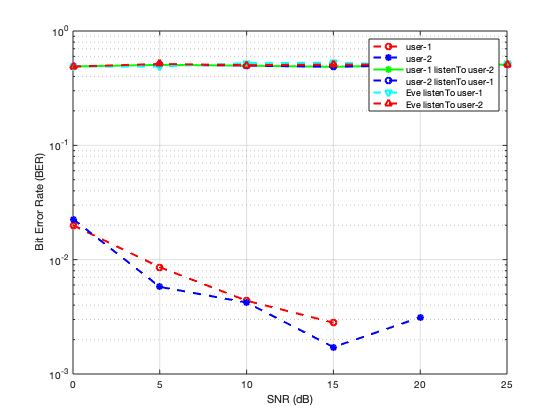

 [BERu11DSISO, BERu11SISO, TERu11DSISO, TERu1_SISO] = WP2_BER_DSISO(N_iter);
%%
 [ber_far_NOMA, ber_near_NOMA] = NOMA_BER_Rayleigh();

%%BER
figure(1);
semilogy(EbN0,BERu11,'or--','LineWidth',2);  hold on;
semilogy(EbN0,BERu21,'*b--','LineWidth',2);  hold on;
semilogy(EbN0,BERIu11,'g-*','LineWidth',2); hold on; %user-1 is eavs
semilogy(EbN0,BERIu21,'b--o','LineWidth',2); hold on;
semilogy(EbN0,BERu1E1,'vc--','LineWidth',2); hold on;
semilogy(EbN0,BERu2E1,'^r--','LineWidth',2); hold on;
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
grid on;
legend('user-1','user-2','user-1 listenTo user-2','user-2 listenTo user-1','Eve listenTo user-1','Eve listenTo user-2','SISO-dual','SISO');

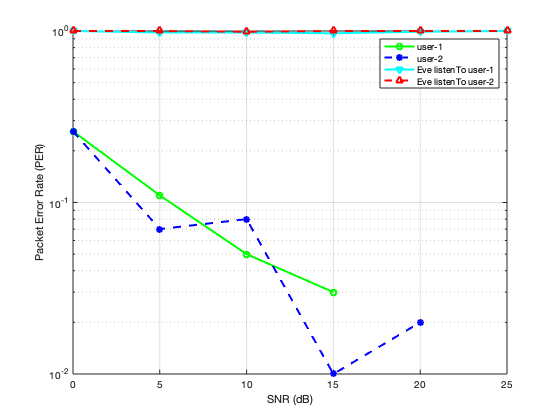

%% PER
figure(2);
semilogy(EbN0,PERu11p,'og-','LineWidth',2); hold on;
semilogy(EbN0,PERu21p,'*b--','LineWidth',2);hold on;
semilogy(EbN0,PBERu1E1p,'vc-','LineWidth',2); hold on;
semilogy(EbN0,PBERu2E1p,'^r--','LineWidth',2);
xlabel('SNR (dB)');
ylabel('Packet Error Rate (PER)');
grid on;
legend('user-1','user-2','Eve listenTo user-1','Eve listenTo user-2');

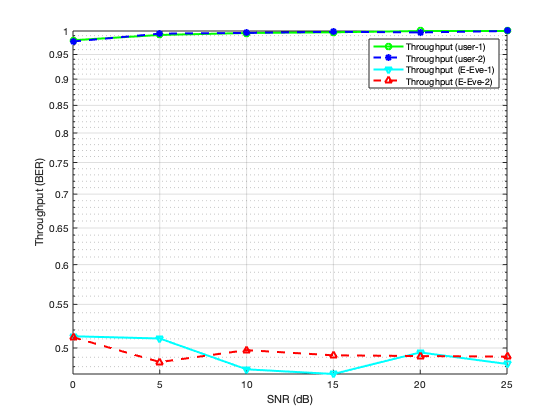


%%TER
figure(3);
semilogy(EbN0,TERu11,'og-','LineWidth',2);hold on;
semilogy(EbN0,TERu21,'*b--','LineWidth',2);hold on;
semilogy(EbN0,TERu1E1,'vc-','LineWidth',2);hold on;
semilogy(EbN0,TERu2E1,'^r--','LineWidth',2);hold on
xlabel('SNR (dB)');
ylabel('Throughput (BER)');
grid on;
legend('Throughput (user-1)','Throughput (user-2)','Throughput  (E-Eve-1)','Throughput (E-Eve-2)','Throughput (SISO)','Throughput (SISO-dual)');

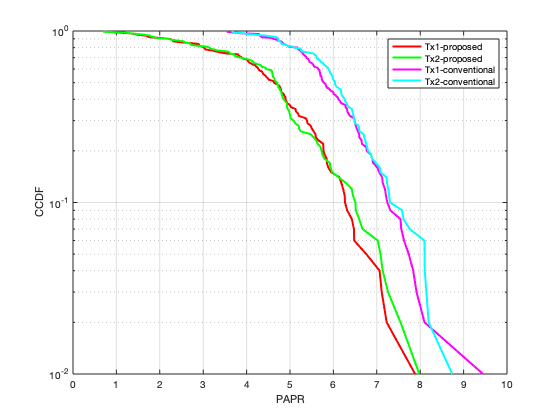

%PAPR
PAPRtx1dB=10*log10(PAPRtx1); % in dB
[F1,X1] = ecdf(PAPRtx1dB); %CDF

PAPRtx2dB=10*log10(PAPRtx2); % in dB
[F2,X2] = ecdf(PAPRtx2dB); %CDF

PAPRtx3dB=10*log10(PAPRtx3); % in dB
[F3,X3] = ecdf(PAPRtx3dB); %CDF

PAPRtx4dB=10*log10(PAPRtx4); % in dB
[F4,X4] = ecdf(PAPRtx4dB); %CDF
figure(4)
semilogy(X1,1-F1,'r','LineWidth',2); hold on; % 1-F1 just to draw the CCDF
semilogy(X2,1-F2,'g','LineWidth',2); hold on;
semilogy(X3,1-F3,'m','LineWidth',2); hold on; % 1-F1 just to draw the CCDF
semilogy(X4,1-F4,'c','LineWidth',2); 
xlabel('PAPR');
ylabel('CCDF');
grid on;
legend('Tx1-proposed','Tx2-proposed','Tx1-conventional','Tx2-conventional');